## Segéd függvények

loglin = @(totalCount, f_floor, f_ceiling) ...
    f_floor .* (f_ceiling/f_floor) .^ ((0:(totalCount -1)) / (totalCount - 1));
% f = frekvencia; a = átmeneti függvény
phase_diff = @(f, a) atan2(imag(a(f)), real(a(f)));
dampening_db = @(f, a) 20 * log10(abs(a(f)));

## 1. feladat

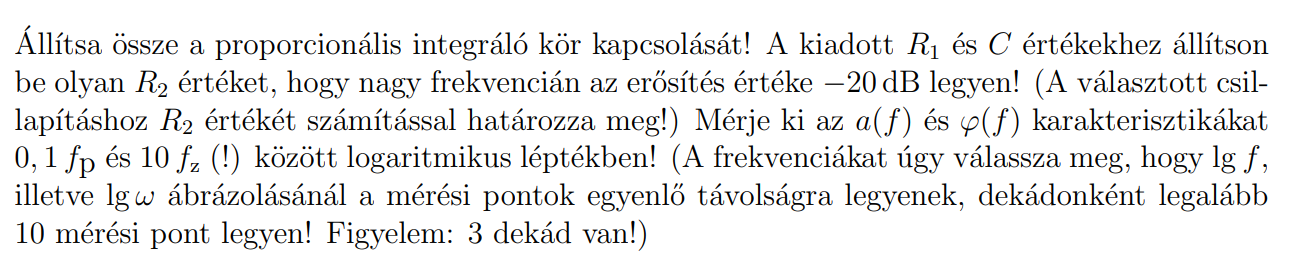

### Adatok

R_1 = 10 * 10^3;
C = 22 * 10^-6;
f_floor_multiplier = 0.1;
f_ceiling_multiplier = 10;
target_dampening_db = -20;

### Ellenállás meghatározása


$$\omega {\;}_z =\frac{1}{R_2 \cdot C},\;\;\omega {\;}_p =\frac{1}{\left(R_1 +R_2 \right)\cdot C}$$



$$a\left(\omega \;\right)=\frac{1+j\frac{\omega }{\omega {\;}_z }\;}{1+j\frac{\omega }{\omega {\;}_p }\;}$$


Ebből láthatjuk, hogy $R_2$kiszámítása egy adott frekvencián, mondjuk $\omega {\;}_t =10000$ lehetséges, mivel tudjuk, hogy 

f_target = 10000;


$$\begin{array}{l}
20\cdot \;\log \left(a\left(\omega {\;}_t \right)\right)\approx -20\mathrm{dB}\\
20\cdot \;\log \left(\left|\frac{1+j\frac{\omega_t }{\omega {\;}_z }\;}{1+j\frac{\omega_t }{\omega {\;}_p }\;}\right|\right)=-20
\end{array}$$


A jegyzet alapján tudjuk, hogy ez ezzel egyenlő


$$\begin{array}{l}
20\cdot \;\log \left(\sqrt{\frac{1+\frac{\omega_t^2 }{\omega {\;}_z^2 }\;}{1+\frac{\omega_t^2 }{\omega {\;}_p^2 }\;}}\right)=-20\\
\log \left({\sqrt{\frac{1+\frac{\omega_t^2 }{\omega {\;}_z^2 }\;}{1+\frac{\omega_t^2 }{\omega {\;}_p^2 }\;}}}^{20} \right)=-20
\end{array}$$


Wolfram alpha megoldja innen


$$R_2 =1111,1$$


R_2 = 1111.1;

f_cutoff = 1 / ((R_1 + R_2) * C);
f_dampen = 1 / ((R_2) * C);
f_floor = f_floor_multiplier * f_cutoff;
f_ceil = f_ceiling_multiplier  * f_dampen;

### Maximum pont


$$\omega {\;}_{\max } =\sqrt{\;\omega {\;}_z \omega {\;}_p }$$


f_max = sqrt(f_cutoff * f_dampen);

### Mérés

effectation = @(f) (1 + 1i * (f / f_dampen)) ./ (1 + 1i * (f / f_cutoff));

f_measure_count = 31;
f_measurements = loglin(f_measure_count, f_floor, f_ceil);

f_damp_calc = dampening_db(f_measurements, effectation);
f_phase_diff_calc = phase_diff(f_measurements, effectation);

f_damp_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];
f_phase_diff_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];

calced_val = table(f_measurements', f_damp_calc', f_phase_diff_calc', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);
disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 31×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°) 
    ______________________    ____________    _________

           0.40909             -0.042779      -0.089669
           0.51502             -0.067603       -0.11265
           0.64837              -0.10665       -0.14133
           0.81625              -0.16781       -0.17699
            1.0276              -0.26299       -0.22098
            1.2937              -0.40959       -0.27467
            1.6286              -0.63204       -0.33908
            2.0503              -0.96234       -0.41452
            2.5812               -1.4382       -0.49986
            3.2495               -2.0971       -0.59201
            4.0909               -2.9671       -0.68573
            5.1502               -4.0562       -0.77429
            6.4837               -5.3477       -0.85075
            8.1625               

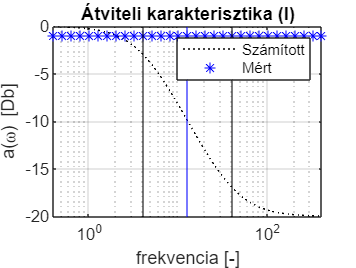


figure();
semilogx(f_measurements, f_damp_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_damp_mes, "b*");
xline(f_cutoff, "k");
xline(f_max, "b");
xline(f_dampen, "k");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

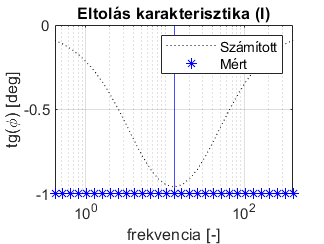


figure();
semilogx(f_measurements, f_phase_diff_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_phase_diff_mes, "b*"); 
xline(f_max, "b");
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])

### 2. feladat

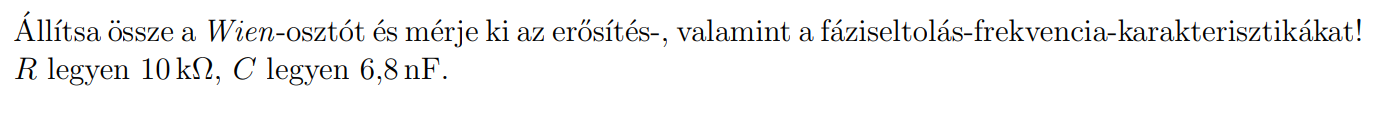

### Adatok

R = 10 * 10^3;
C = 6.8 * 10^-6;

### Számítás


$$Z_1 =R+\frac{1}{\textrm{jC}\omega \;},Z_2 =\frac{1}{\frac{1}{R}+\textrm{jC}\omega \;}$$



$$a\left(\omega \;\right)=\frac{Z_2 }{Z_1 +Z_2 }$$


Z_1 = @(f) R + (1 ./ (1i .* C .* f));
Z_2 = @(f) 1 ./ ((1/R) + 1i .* C .* f);

effectation = @(f) Z_2(f) ./ (Z_1(f) + Z_2(f));

f_passthrough = 1 / (R * C);

### Mérések

f_floor = f_passthrough * 10^-2;
f_ceil = f_passthrough * 10^4;
f_measure_count = 21;

f_measurements = loglin(f_measure_count, f_floor, f_ceil);

f_damp_calc = dampening_db(f_measurements, effectation);
f_phase_diff_calc = phase_diff(f_measurements, effectation);

f_damp_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];
f_phase_diff_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];

calced_val = table(f_measurements', f_damp_calc', f_phase_diff_calc', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);
disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 21×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

           0.14706              -40.003         1.5408
           0.29342              -34.012          1.511
           0.58545              -28.048         1.4517
            1.1681              -22.188         1.3354
            2.3307              -16.706          1.117
            4.6504               -12.33        0.75907
            9.2788              -9.9607        0.30787
            18.514              -9.6454       -0.15365
             36.94              -11.293        -0.6138
            73.704              -15.073        -1.0134
            147.06              -20.294        -1.2766
            293.42              -26.076        -1.4212
            585.45              -32.019        -1.4955
            1168.1              -38.005         

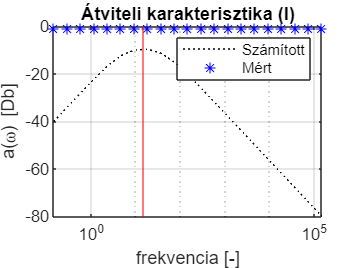


figure();
semilogx(f_measurements, f_damp_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_damp_mes, "b*");
xline(f_passthrough, "r");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

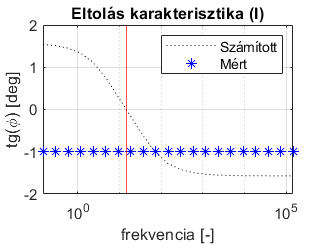


figure();
semilogx(f_measurements, f_phase_diff_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_phase_diff_mes, "b*"); 
xline(f_passthrough, "r");
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])